% Load the ECG data
data = readtable('ekg.csv');


% Extract time and signal values
time = data.('Time_s_');
ecg_signal = data.('Channel1_V_');

% Display the first few rows of the data for verification
disp('First few rows of the ECG data:');

First few rows of the ECG data:


disp(data(1:10, :));

    Time_s_    Channel1_V_
    _______    ___________

    -1.1293     -0.015717 
     -1.129     -0.013341 
    -1.1287     -0.015038 
    -1.1285     -0.012662 
    -1.1282     -0.015378 
     -1.128     -0.013341 
    -1.1278     -0.017414 
    -1.1275     -0.015717 
    -1.1273     -0.018772 
     -1.127     -0.017414 



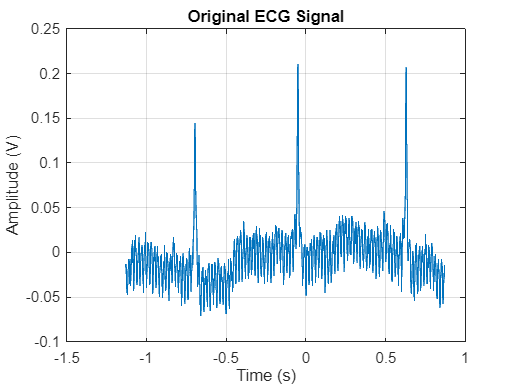


% Plot the original ECG signal
figure;
plot(time, ecg_signal);
title('Original ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

% Define filter specifications
fs = 200;  % Sampling frequency
Wp = [6 40] / (fs / 2);  % Passband edge frequencies (normalized)
Ws = [1 45] / (fs / 2);  % Stopband edge frequencies (normalized)
Rp = 1;   % Passband ripple in dB
Rs = 40;  % Stopband attenuation in dB

% Design Butterworth filter
[n_butt, Wn_butt] = buttord(Wp, Ws, Rp, Rs);
[b_butt, a_butt] = butter(n_butt, Wn_butt);

% Design Chebyshev Type I filter
[n_cheb1, Wp_cheb1] = cheb1ord(Wp, Ws, Rp, Rs);
[b_cheb1, a_cheb1] = cheby1(n_cheb1, Rp, Wp_cheb1);

% Design Chebyshev Type II filter
[n_cheb2, Ws_cheb2] = cheb2ord(Wp, Ws, Rp, Rs);
[b_cheb2, a_cheb2] = cheby2(n_cheb2, Rs, Ws_cheb2);

% Design Elliptic filter
[n_ellip, Wp_ellip] = ellipord(Wp, Ws, Rp, Rs);
[b_ellip, a_ellip] = ellip(n_ellip, Rp, Rs, Wp_ellip);

% Display filter orders
disp('Filter Orders:');

Filter Orders:


disp(['Butterworth: ', num2str(n_butt)]);

Butterworth: 27


disp(['Chebyshev Type I: ', num2str(n_cheb1)]);

Chebyshev Type I: 10


disp(['Chebyshev Type II: ', num2str(n_cheb2)]);

Chebyshev Type II: 10


disp(['Elliptic: ', num2str(n_ellip)]);

Elliptic: 5


% Apply the Butterworth filter
ecg_butt = filtfilt(b_butt, a_butt, ecg_signal);

% Apply the Chebyshev Type I filter
ecg_cheb1 = filtfilt(b_cheb1, a_cheb1, ecg_signal);

% Apply the Chebyshev Type II filter
ecg_cheb2 = filtfilt(b_cheb2, a_cheb2, ecg_signal);

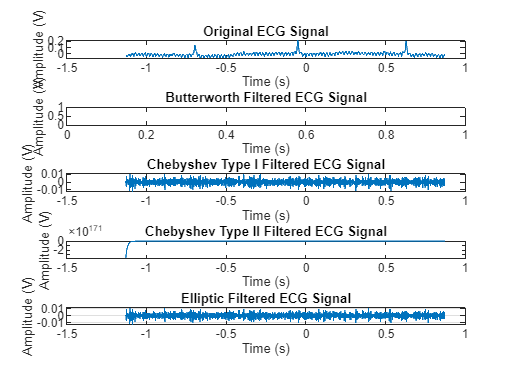


% Apply the Elliptic filter
ecg_ellip = filtfilt(b_ellip, a_ellip, ecg_signal);

% Plot the original and filtered signals in the time domain
figure;
subplot(5, 1, 1);
plot(time, ecg_signal);
title('Original ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude (V)');

subplot(5, 1, 2);
plot(time, ecg_butt);
title('Butterworth Filtered ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude (V)');

subplot(5, 1, 3);
plot(time, ecg_cheb1);
title('Chebyshev Type I Filtered ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude (V)');

subplot(5, 1, 4);
plot(time, ecg_cheb2);
title('Chebyshev Type II Filtered ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude (V)');

subplot(5, 1, 5);
plot(time, ecg_ellip);
title('Elliptic Filtered ECG Signal');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

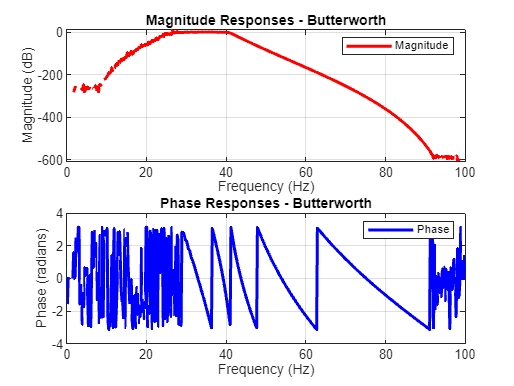

% Frequency response of each filter
[H_butt, w_butt] = freqz(b_butt, a_butt);
[H_cheb1, w_cheb1] = freqz(b_cheb1, a_cheb1);
[H_cheb2, w_cheb2] = freqz(b_cheb2, a_cheb2);
[H_ellip, w_ellip] = freqz(b_ellip, a_ellip);

% Plot magnitude and phase responses of each filter
figure;

% Plot magnitude and phase responses of Butterworth filter
subplot(2, 1, 1);
plot(w_butt/pi*fs/2, 20*log10(abs(H_butt)), 'r', 'LineWidth', 2);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude Responses - Butterworth');
legend('Magnitude');

subplot(2, 1, 2);
plot(w_butt/pi*fs/2, angle(H_butt), 'b', 'LineWidth', 2);
grid on;
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
title('Phase Responses - Butterworth');
legend('Phase');

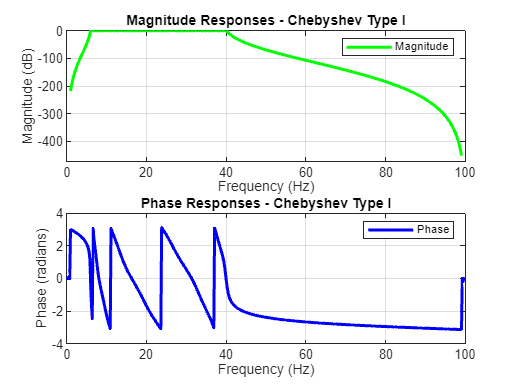


% Plot magnitude and phase responses of Chebyshev Type I filter
figure;

subplot(2, 1, 1);
plot(w_cheb1/pi*fs/2, 20*log10(abs(H_cheb1)), 'g', 'LineWidth', 2);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude Responses - Chebyshev Type I');
legend('Magnitude');

subplot(2, 1, 2);
plot(w_cheb1/pi*fs/2, angle(H_cheb1), 'b', 'LineWidth', 2);
grid on;
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
title('Phase Responses - Chebyshev Type I');
legend('Phase');

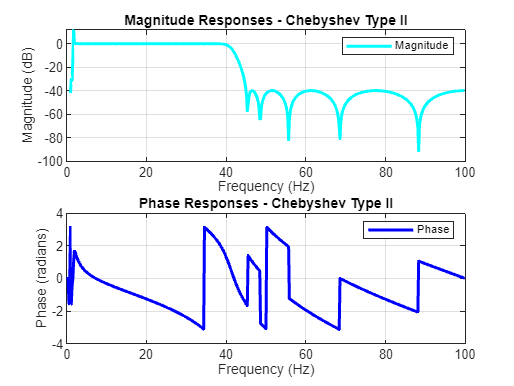


% Plot magnitude and phase responses of Chebyshev Type II filter
figure;

subplot(2, 1, 1);
plot(w_cheb2/pi*fs/2, 20*log10(abs(H_cheb2)), 'c', 'LineWidth', 2);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude Responses - Chebyshev Type II');
legend('Magnitude');

subplot(2, 1, 2);
plot(w_cheb2/pi*fs/2, angle(H_cheb2), 'b', 'LineWidth', 2);
grid on;
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
title('Phase Responses - Chebyshev Type II');
legend('Phase');

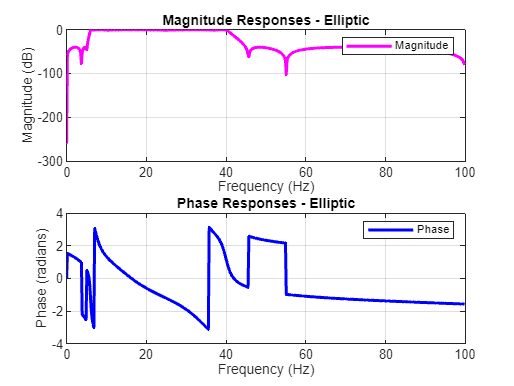


% Plot magnitude and phase responses of Elliptic filter
figure;

subplot(2, 1, 1);
plot(w_ellip/pi*fs/2, 20*log10(abs(H_ellip)), 'm', 'LineWidth', 2);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Magnitude Responses - Elliptic');
legend('Magnitude');

subplot(2, 1, 2);
plot(w_ellip/pi*fs/2, angle(H_ellip), 'b', 'LineWidth', 2);
grid on;
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
title('Phase Responses - Elliptic');
legend('Phase');

% Plot magnitude and phase responses of the original and filtered ECG signals
figure;
% Calculate the FFT of the signals
n = length(ecg_signal);
f = (0:n-1)*(fs/n);

% Original ECG signal
fft_orig = fft(ecg_signal);
mag_orig = abs(fft_orig);
phase_orig = angle(fft_orig);

% Butterworth filtered ECG signal
fft_butt = fft(ecg_butt);
mag_butt = abs(fft_butt);
phase_butt = angle(fft_butt);

% Chebyshev Type I filtered ECG signal
fft_cheb1 = fft(ecg_cheb1);
mag_cheb1 = abs(fft_cheb1);
phase_cheb1 = angle(fft_cheb1);

% Chebyshev Type II filtered ECG signal
fft_cheb2 = fft(ecg_cheb2);
mag_cheb2 = abs(fft_cheb2);
phase_cheb2 = angle(fft_cheb2);

% Elliptic filtered ECG signal
fft_ellip = fft(ecg_ellip);
mag_ellip = abs(fft_ellip);
phase_ellip = angle(fft_ellip);

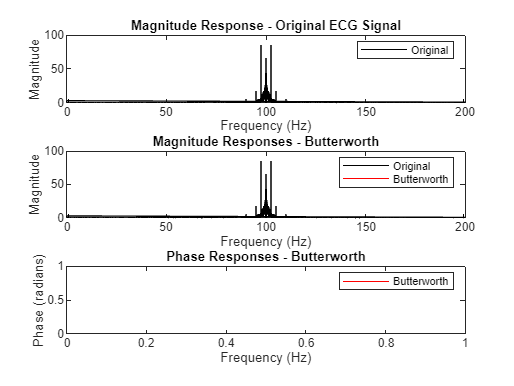

% Plot magnitude and phase responses of the original and filtered ECG signals
figure;

% Shift frequencies
f_shifted = fftshift(f);

% Plot the magnitude responses and original signal
subplot(3, 1, 1);
plot(f_shifted, mag_orig, 'k', 'DisplayName', 'Original');
title('Magnitude Response - Original ECG Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend show;

subplot(3, 1, 2);
plot(f_shifted, mag_orig, 'k', 'DisplayName', 'Original');
hold on;
plot(f_shifted, mag_butt, 'r', 'DisplayName', 'Butterworth');
hold off;
title('Magnitude Responses - Butterworth');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend show;

subplot(3, 1, 3);
plot(f_shifted, unwrap(phase_butt), 'r', 'DisplayName', 'Butterworth');
title('Phase Responses - Butterworth');
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
legend show;

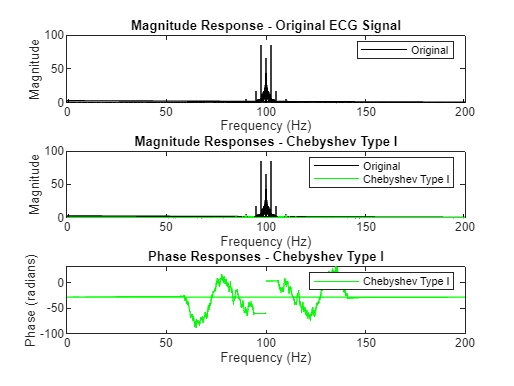


% Plot the magnitude responses and original signal
figure;

subplot(3, 1, 1);
plot(f_shifted, mag_orig, 'k', 'DisplayName', 'Original');
title('Magnitude Response - Original ECG Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend show;

subplot(3, 1, 2);
plot(f_shifted, mag_orig, 'k', 'DisplayName', 'Original');
hold on;
plot(f_shifted, mag_cheb1, 'g', 'DisplayName', 'Chebyshev Type I');
hold off;
title('Magnitude Responses - Chebyshev Type I');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend show;

subplot(3, 1, 3);
plot(f_shifted, unwrap(phase_cheb1), 'g', 'DisplayName', 'Chebyshev Type I');
title('Phase Responses - Chebyshev Type I');
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
legend show;

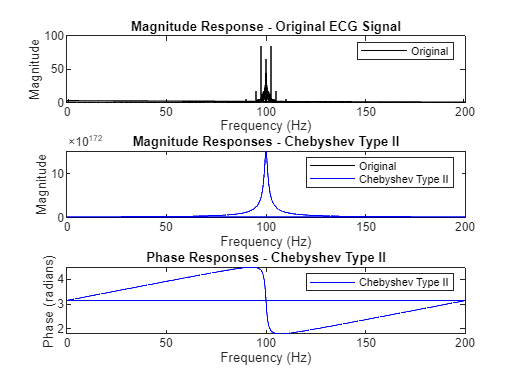


% Plot the magnitude responses and original signal
figure;

subplot(3, 1, 1);
plot(f_shifted, mag_orig, 'k', 'DisplayName', 'Original');
title('Magnitude Response - Original ECG Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend show;

subplot(3, 1, 2);
plot(f_shifted, mag_orig, 'k', 'DisplayName', 'Original');
hold on;
plot(f_shifted, mag_cheb2, 'b', 'DisplayName', 'Chebyshev Type II');
hold off;
title('Magnitude Responses - Chebyshev Type II');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend show;

subplot(3, 1, 3);
plot(f_shifted, unwrap(phase_cheb2), 'b', 'DisplayName', 'Chebyshev Type II');
title('Phase Responses - Chebyshev Type II');
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
legend show;

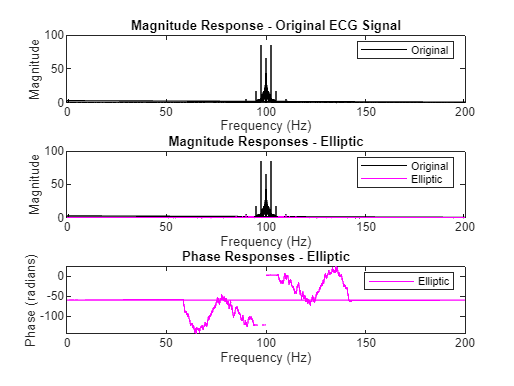


% Plot the magnitude responses and original signal
figure;

subplot(3, 1, 1);
plot(f_shifted, mag_orig, 'k', 'DisplayName', 'Original');
title('Magnitude Response - Original ECG Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend show;

subplot(3, 1, 2);
plot(f_shifted, mag_orig, 'k', 'DisplayName', 'Original');
hold on;
plot(f_shifted, mag_ellip, 'm', 'DisplayName', 'Elliptic');
hold off;
title('Magnitude Responses - Elliptic');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend show;

subplot(3, 1, 3);
plot(f_shifted, unwrap(phase_ellip), 'm', 'DisplayName', 'Elliptic');
title('Phase Responses - Elliptic');
xlabel('Frequency (Hz)');
ylabel('Phase (radians)');
legend show;